clear;
clc;

addpath(genpath(pwd));

%% fingerprint range & index of consitituents
lower_limit=500;higher_limit=1800;
calibrated_axis=load('QePro_NIR_spectrum_axis2.txt');
[~, fp_low] = min(abs(calibrated_axis - lower_limit));
[~, fp_high] = min(abs(calibrated_axis - higher_limit));
fp=fp_low:1:fp_high; % pixel range(say) but fp range 799-1900cm-1
fp_axis=calibrated_axis(fp);
[~, GAGindex] = min(abs(fp_axis - 1075));
[~, Colindex] = min(abs(fp_axis - 1458));
[~, pbsindex] = min(abs(fp_axis - 1653));


## Pure reference spectras for non negative least squares

% GAG
referenceSignal1 = load("C:\Users\VK\MATLAB Drive\DATA\pure cartilage\XY-with-std-deviation-red/processed_n_pure-gag-2s.mat") ;
referenceSignal1=referenceSignal1.data_struct.x;% Known reference signal 1

% Collagen
referenceSignal2 = load("C:\Users\VK\MATLAB Drive\DATA\pure cartilage\XY-with-std-deviation-red/processed_n_pure-coltype2-2s.mat");  % Known reference signal 2
referenceSignal2=referenceSignal2.data_struct.x;

% PBS
referenceSignal3 = load("C:\Users\VK\MATLAB Drive\DATA\pure cartilage\XY-with-std-deviation-red/processed_n_pure-pbs-2s.mat");  % Known reference signal 2
referenceSignal3=referenceSignal3.data_struct.x;

% Construct the matrix A in Ax = b
A = [referenceSignal1(:), referenceSignal2(:), referenceSignal3(:)];

data=load('D:\ConfocaL Raman\Confocal_data\2023-10-02\scan_2000ms_65F_824x762_to_25pxby15px');


data=data.data.ItemsData;

data=data{1,1};

%data=squeeze(data(:,:,1,:));
data=squeeze(data(:,:,1,fp));

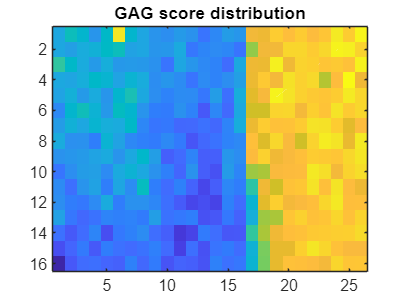

% Spectra for mean background
spectra_2d = reshape(data(1:5,1:5,:), [], length(fp));

% Calculate the mean spectra for background
mean_spectra = mean(spectra_2d);
mean_spectra= cosmicRemoval(mean_spectra);
%mean_spectra=mean_spectra(fp);

% Spectra for mean background
spectra_2d1 = reshape(data, [], length(fp));

% Subtract the mean spectra from each pixel's spectrum
%spectra_mm = spectra_2d1 - mean_spectra;



for i=1:size(spectra_2d1(:,1))
   
    red_d_cos=spectra_2d1(i,:);
    bg_rem_d=bgRemoval(red_d_cos,mean_spectra);
    %baseline correction
    to_s_d=baseCorrection(squeeze(bg_rem_d));
    %smoothening
    to_n_d=smoothening(squeeze(to_s_d));
    n_d=normm(to_n_d);
    spectra_2d2(i,:)=n_d;

    % Solve for coefficients using NNLS
    X = lsqnonneg(A, n_d(:));
    
    % Reconstruct resolved signals
    % resolvedSignal1 = X(1) * referenceSignal1;
    % resolvedSignal2 = X(2) * referenceSignal2;
    % resolvedSignal3 = X(3) * referenceSignal3;
    score_gag(i,:) =X(1);
    score_collagen(i,:) =X(2);
    score_pbs(i,:)=X(3);
end


%original 3D shape for processed data
spectra_mm_3d = reshape(spectra_2d2, size(data));

% all wavenumber plots
% for i =1:1044
%     i
%     figure;
%     imagesc(spectra_mm_3d(:, :, i));
%     hold off;
% end

%2D map
score_gag_map=reshape(score_gag, size(squeeze(data(:,:,1))));
score_col_map=reshape(score_collagen, size(squeeze(data(:,:,1))));
score_pbs_map=reshape(score_pbs, size(squeeze(data(:,:,1))));



%univariate
%% GAG & Col and PBS distribution
% figure;
% imagesc(spectra_mm_3d(:, :, GAGindex));
% title('GAG distribution');
% hold off;

figure;
imagesc(score_gag_map);
title('GAG score distribution');
hold off;

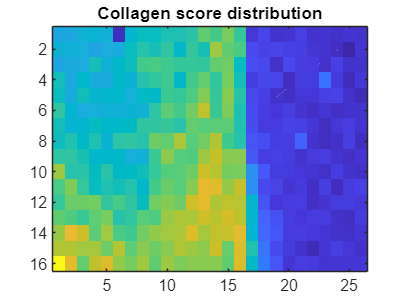


figure;
imagesc(score_col_map);
title('Collagen score distribution');
hold off;

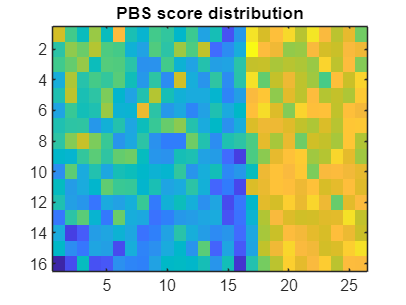


figure;
imagesc(score_pbs_map);
title('PBS score distribution');
hold off;

Cosmic Ray

function to_bg_sb=cosmicRemoval(spectrum)
    window_size=5;
    to_bg_sb = medfilt1(spectrum, window_size);
end

Background removal

function bg_rem_data=bgRemoval(spectrum,bg)
    bg_rem_data=spectrum-bg;
end

Baseline correction

function to_smooth = baseCorrection(bg_rem_data)
    polynomial_fp_order=4;
    spectrumm=bg_rem_data;
    spec=spectrumm;
    
    initial = true;
    while initial || overshoot_count > 24
        initial = false;
    
        polynomial_coefficients = polyfit(1:length(spec), spec, polynomial_fp_order);
        polynomial_values = polyval(polynomial_coefficients, 1:length(spec));
        
        overshoot_indices = polynomial_values > spectrumm;
        polynomial_values(overshoot_indices) = spectrumm(overshoot_indices);
        overshoot_count = sum(overshoot_indices);
    
        spec = polynomial_values;
        
    end
    %% base corrrected
    to_smooth= (spectrumm - spec);
end


Smoothening

function to_norm = smoothening(to_smooth)
    sgolay_width=3;
    to_norm = sgolayfilt(to_smooth, 1, sgolay_width);
end

Normalization

function normalised = normm(to_norm)
    normalised = to_norm/trapz(to_norm);
end    